# Example 2.1: Pdf and Cdf of Discrete Uniform RV

Note: this script reproduces Example 2.1 (Section 2.1.1) of **Statistics for Chemical Engineers**: a discrete uniform RV, whose values are all equally likely. Victor Z UW-Madison, 2020 pdf and cdf of a discrete uniform RV

clc; clear all; close all hidden;

## Pdf

pdf

a=-1; b=+1; x=a:1:b; n=b-a+1;
f=ones(n,1)*(1/n);

## Realizations

generate samples

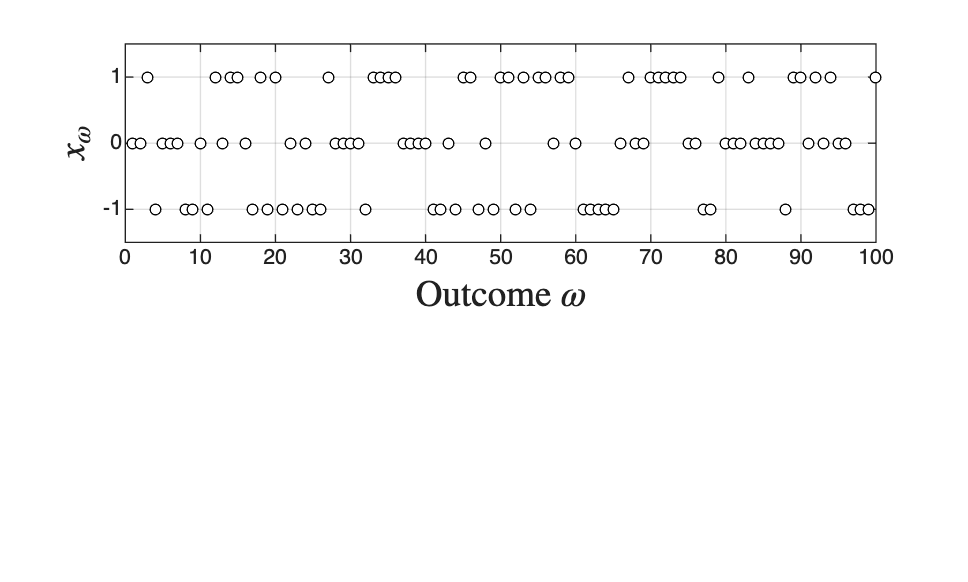

S=100;
X=unidrnd(3,S,1);
X=X-2;
figure(1)
subplot(2,2,[1 2])
plot(X,'blacko','MarkerFaceColor','w','MarkerSize',4)
xlabel('Outcome $\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
grid on
yticks([-1 0 1])
axis([0 S -1.5 1.5])

## Cdf

compute cdf using pdf

t = linspace(-2,2);
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
        F(i)=F(i)+(x(j)<=t(i))*f(j);
    end
end

## Plots

visualize pdf

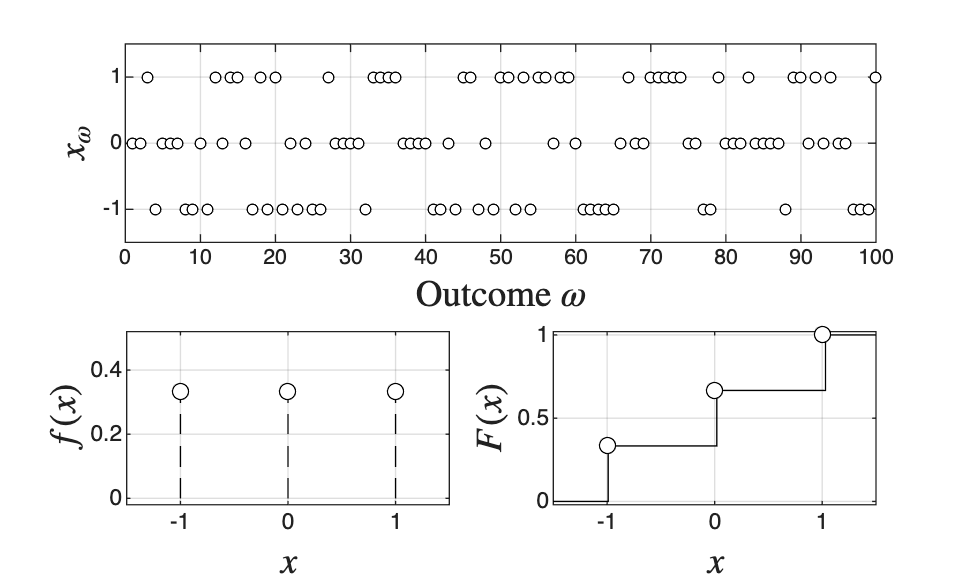

figure(1)
subplot(2,2,3)
for j=1:n
    plot(x(j)*ones(100,1),linspace(0,f(j),100),'black--')
    hold on
end
scatter(x,f,'MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([-1.5 1.5 -0.02 0.52])

% visualize cdf
subplot(2,2,4)
stairs(t,F,'black-')
hold on
for j=1:n
    Fn(j)=(floor(x(j))-a+1)/n;
    scatter(x(j),Fn(j),'MarkerFaceColor','w','MarkerEdgeColor','black')
    hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
axis([-1.5 1.5 -0.02 1.02])

print -depsc ch2_pdfcdfuniformd.eps

## Note

As in the book, the density is the same for all domain values: there is no trend in the realizations, but each value appears with equal probability.